## 1.Gaussian beam simulation

### 1.1光束横截面光强分布

高斯光束的参数以及表达形式：


$$U\left(r\right)=A_0\frac{W_0}{W\left(z\right)}exp\left[-\frac{\rho^2}{W^2\left(z\right)}\right]exp\left[-jkz-jk\frac{\rho^2}{2R\left(z\right)}+j\eta\left(z\right)\right]$$



$$其中，W\left(z\right)=W_0\sqrt{1+\left(\frac{z}{z_0}\right)^2}，W_0=\sqrt{\frac{\lambda z_0}{\pi}}，R\left(z\right)=z\left[1+\left(\frac{z_0}{z}\right)^2\right]，\eta\left(z\right)={tan}^{-1}\frac{z}{z_0}为古伊相移(Gouy shift)。$$


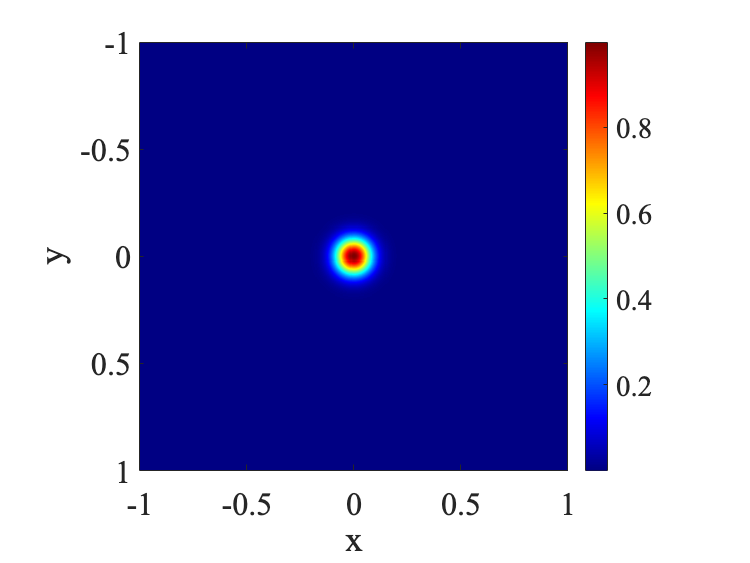

%%%%%%%%定义光束参数%%%%%%%%
w0 = 1.2e-3;  %光束束腰半径
lambda = 1064e-9;   %波长
z0 = w0^2 * pi / lambda;  %瑞利半径z0
k = 2 * pi / lambda;  %波数

%%%%%%%%光束沿z轴传播%%%%%%%%
Ld = 5;  %沿z轴传播距离
Rd =2*w0;  %径向范围  
%%生成网格
N = 200;  %网格点的数量
zd = linspace(-Ld, Ld, 2*N-1); %横轴
rd = linspace(-Rd, Rd, N); %纵轴
[z, r] = meshgrid(zd, rd); %网格平面

%%%%%%%%计算高斯光束参数%%%%%%%%
eta = atan(z / z0);  %计算Gouy相移
q = z + 1i * z0;     %计算q参数
R = 1./(real(1./q)); %计算曲率半径R
w = sqrt(1 ./ (-pi / lambda * imag(1 ./ q)));  %计算束宽w

%%%%%%%%计算光束的复振幅并归一化，计算光强%%%%%%%%
E = w0 ./ w .* exp(-r.^2 ./ w.^2) .*...
exp(-1i *k * z - 1i * k * r.^2 ./(2 * R)+1i*eta);  % 归一化后的复振幅
E = E / max(max(abs(E)));  %归一化光场复振幅
I = abs(E).^2;  %计算光强


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘制光束横向剖面%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 空间网格 (用于光束截面)
lx=10*w0;%length on the x dimension
ly=10*w0;%length on tne y dimension
nx=500;%x-axis pixels
ny=500;%y-axis pixels
x = linspace(-lx,lx,nx); % x坐标
y = linspace(-ly,ly,ny); % y坐标
[X, Y] = meshgrid(x, y);

% 当前z位置的束腰宽度
 w= w0 * sqrt(1 + (0 / z0)^2);
% wx = w0 * sqrt(1 + (0 / z0)^2); % 计算当前z的x方向束腰宽
% wy = w0 * sqrt(1 + (0 / z0)^2); % 计算当前z的y方向束腰宽

% % 光强分布计算
I0 = exp(-2 * (X.^2 + Y.^2)./ w.^2); % 高斯光束强度分布

% 绘制横向剖面
figure;
imagesc(x * 1e2, y * 1e2, I0); % 绘制光束截面
colormap jet
% title(['光束截面在 z = ', num2str(0, '%.2f'), ' 米处']);
axis image;
% 设置坐标轴标签
set(gca,'FontName','Times New Roman', 'FontSize', 24);%设置刻度线字体和大小
xlabel('\fontname{Times New Roman}x', 'FontSize', 26);
ylabel('\fontname{Times New Roman}y', 'FontSize', 26);

xlim([-1.00 1.00])
ylim([-1.00 1.00])
colorbar

### 1.2沿光束传播方向电场和波前曲率半径分布

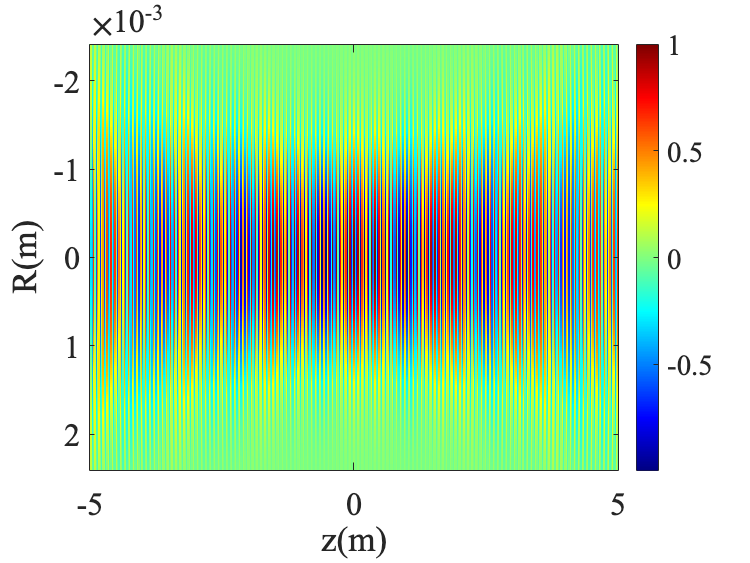


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘制光束纵向剖面%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
imagesc(zd, rd,real(E));%电场强度分布
colormap jet;
hold on;
plot(zd, w, 'r', zd, -w, 'r', 'LineWidth', 3); %光束上下界限-束宽
% 设置坐标轴标签
set(gca,'FontName','Times New Roman', 'FontSize', 24);%设置刻度线字体和大小
xlabel('\fontname{Times New Roman}z(m)', 'FontSize', 26);
ylabel('\fontname{Times New Roman}R(m)', 'FontSize', 26);
colorbar

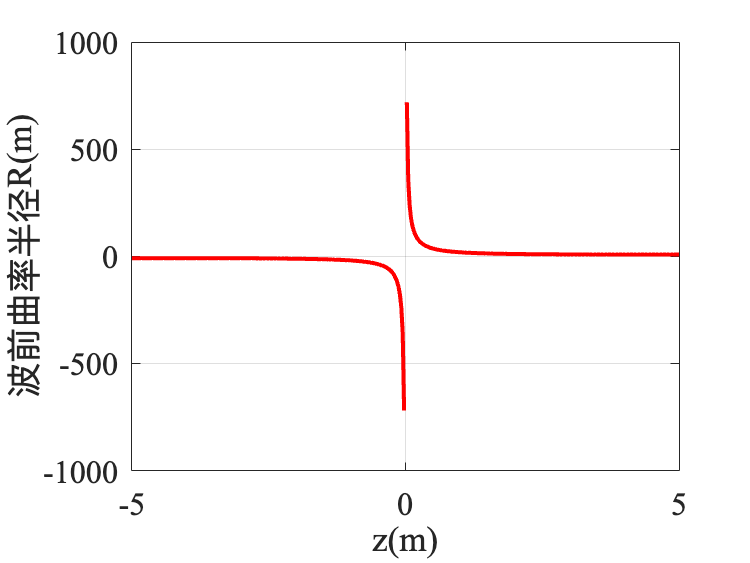

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘制波前曲率半径变化%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
plot(zd, R,'r', 'LineWidth', 3);
xlabel('\fontname{Times New Roman}z(m)', 'FontSize', 26);
ylabel('\fontname{宋体}波前曲率半径\fontname{Times New Roman}R(m)', 'FontSize', 26);
set(gca,'FontName','Times New Roman', 'FontSize', 24);%设置刻度线字体和大小
% title('波前曲率半径随传播距离 z 变化');
grid on;

### 1.3光束三维空间图

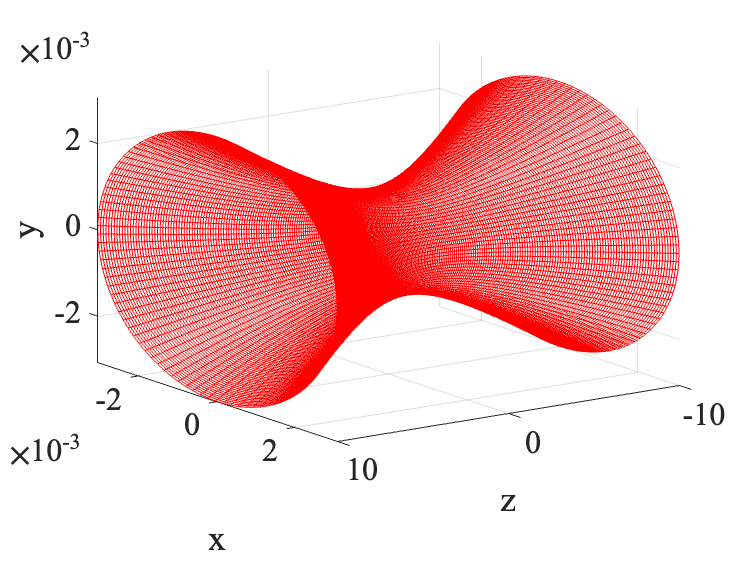


%%%%%%%%%%%%%%%%%%%%%%%%%%%%绘制光束三维空间图%%%%%%%%%%%%%%%%%%%%%%%%%
w0x =w0; % x方向的光束腰宽度 (单位: 米)
w0y = w0; % y方向的光束腰宽度 (单位: 米)
z0x = 0; % x方向焦点位置 (单位: 米)
z0y = 0; % y方向焦点位置 (单位: 米)

%计算瑞利长度
zRx = pi * w0x^2 / lambda; %x方向瑞利长度
zRy = pi * w0y^2 / lambda; %y方向瑞利长度

z_vals = linspace(-10, 10, 200);  %传播距离范围 (单位: 米)
theta = linspace(0, 2*pi, 100);  %椭圆角度范围

%准备光束轮廓数据
[X, Y, Z] = deal([]);
for z = z_vals
    %当前z位置的束腰宽度
    w = w0x * sqrt(1 + ((z - z0x) / zRx)^2);
    wy = w0y * sqrt(1 + ((z - z0y) / zRy)^2);
    
    %椭圆截面
    x = w * cos(theta);
    y = wy * sin(theta);
    
    %将截面扩展到三维空间
    X = [X; x];
    Y = [Y; y];
    Z = [Z; z * ones(size(theta))];
end

% 绘制光束的三维几何轮廓

figure;
mesh(Z, X, Y , 'EdgeColor', 'red'); % 绘制网格轮廓
hold on;

% 设置坐标轴标签
xlabel('\fontname{Times New Roman}z', 'FontSize', 26);
ylabel('\fontname{Times New Roman}x', 'FontSize', 26);
zlabel('\fontname{Times New Roman}y', 'FontSize', 26);
set(gca,'FontName','Times New Roman', 'FontSize', 24);%设置刻度线字体和大小
% 设置标题和轴属性
axis tight;
grid on;
view(145, 20); % 设置视角
hold off;

### 1.4高斯光束衍射

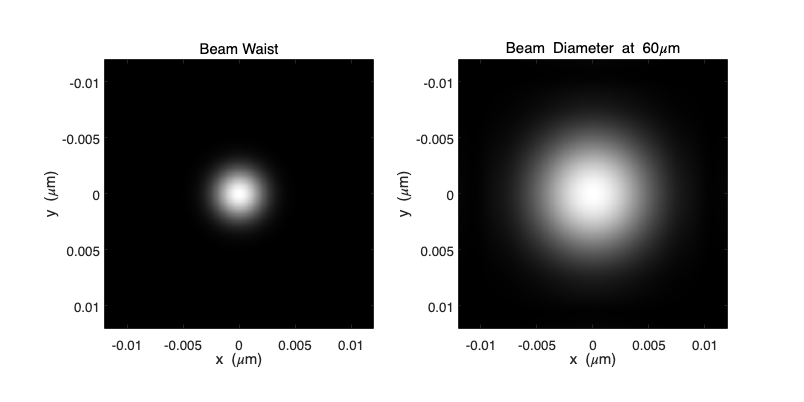

x=linspace(-lx,ly,nx);
y=linspace(-lx,ly,ny);
[X,Y]=ndgrid(x,y);
kx=2*pi/(x(end)-x(1))*((-nx/2):(nx/2-1));
ky=2*pi/(y(end)-y(1))*((-nx/2):(ny/2-1));
[Kx,Ky]=ndgrid(kx,ky);


E0=exp(-(X.^2 + Y.^2)./w.^2);
E0_hat=fftshift(fft2(fftshift(E0)));
z=60;

%近轴近似
E_z_hat=E0_hat.*exp(1i.*k*(1-1/2*(Kx/k).^2-1/2*(Ky/k).^2).*z);
E_z=fftshift(ifft2(fftshift(E_z_hat)));
I_z=abs(E_z).^2;


figure()
subplot(121)
imagesc(x,x,abs(E0).^2)
title('Beam Waist')
xlabel('x (\mum)')
ylabel('y (\mum)')
axis image
colormap gray

subplot(122)
imagesc(x,x,I_z)
title(['Beam Diameter at ', num2str(z), '\mum'])
xlabel('x (\mum)')
ylabel('y (\mum)')
axis image
set(gcf,'Position', [100 100 600 300])